# 01_python from matlab learn/teach

Peter Chang 2026/Aug/7

## Matrix manipulation in MATLAB then using numpy

This .mlx serves as a template to learning/teaching:

“What concept am I using in MATLAB, and what is the corresponding Python concept?”

"How do I manage the runtime objects that can be used as messages/data transferred between the two programs?"

### "list" in python and "arrays" in matlab

- how they are different

- how cell array in matlab are closer to python's list

- basic caller function in matlab to run python

#### both matlab and python are "translational/interpreted languages" not "compiler languages"

- Both MATLAB and Python are primarily interpreted, high-level programming languages (both also use modern JIT compilation internally).

- Both require an installed runtime environment and are supported on Windows, Linux, and macOS.

- Neither is primarily intended to produce standalone native Executables like C or C++, although both can generate deployable applications with additional tools.

- Both excel at numerical computing, simulation, data analysis, visualization, automation, and batch processing.

- Python has a much broader ecosystem for operating systems, networking, AI, web services, cloud computing, and robotics. It is open source with a very large community.

- MATLAB focuses on scientific computing, engineering, modeling, simulation, optimization, signal processing, control systems, and rapid research development.

- MATLAB and Python complement each other well. MATLAB is often used to develop and verify algorithms, while Python is commonly used to integrate those algorithms into larger software systems, AI pipelines, ROS 2 applications, and cross-platform deployments.

## Installation on same windows system to run Python in MATLAB

note on August 2026, matlab only support python 3.13.15

### Choose right python to run in matlab

It can be a version lower then the most recent one for standalone python. Install all Python under system wide availability, but note later we will be using VS code along with Jupiter notebook like MATLAB's live script. So make sure all environment are properly setup.

- MATLAB

- Python

- VS code

Understand they all are different, but as IDE or as "compiler/interpretation" computer languages, all the subsystem/subfunction/subroutine, class object oriented and controller flow, data/list/array/dictionary/memory management are all the same with different objectives.

### MATLAB environment with Python integration

- matlab command line is ">>"

- python command line is ">>>"

- most use VS code as the direct .py or .ipynb editor

- matlab can use the .mlx similar to .ipynb to move into this transition

### MATLAB calling python runtime variables and itself as an object

- using an object to py.getthings(withoptions)

- run .py files, as well as having standard python file "standalone" Executables

- use a MATLAB Cell array to receive this python list object

## A most simple start with a b02_python_list_example.py file

### Ready a .py file in the form of:

%---- the following comments in matlab is for python coding ---%
% # python example creating 2 lists
% numbers = [1, 2, 3, 4]
% mixed = [1, "peter", 3.14, True]

% numberss = [float(x) for x in numbers]

The above code should be ready to run under the .py filename ("b02_python_list_example.py")

This is best written with vs code IDE:

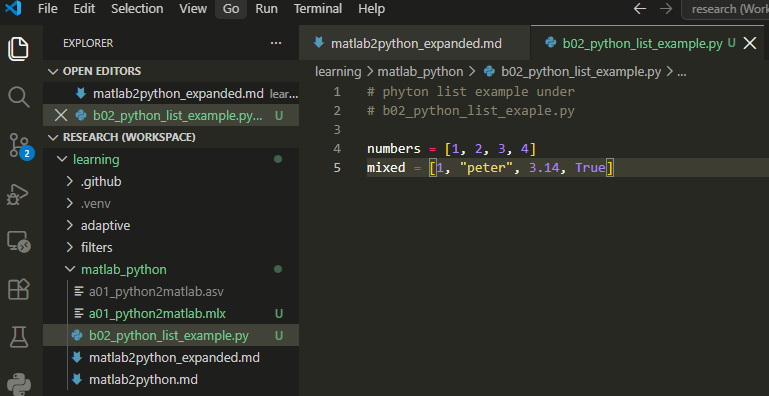

#### Test calling these python objects and assign them into MATLAB cell arrays.

note that there are multiple ways and object to consider the message/data transference

pyrunfile("b02_python_list_example.py")

pyNumbers = pyrun("import b02_python_list_example as p; result = p.numbers", ...
    "result");

disp(pyNumbers)

  Python list with values:

    [1, 2, 3, 4]

    Use string, double or cell function to convert to a MATLAB array.




pyNumberss = pyrun("import b02_python_list_example as p; result = p.numberss", ...
    "result");

disp(pyNumberss)

  Python list with values:

    [1.0, 2.0, 3.0, 4.0]

    Use string, double or cell function to convert to a MATLAB array.



#### Explaining pyrunfile and pyrun functions

references: [here](https://www.mathworks.com/help/matlab/ref/runpythoncode.html)

#### Multiple ways to run stand-alone python 3.13 (or others) objects

- python command line ">>>" inside 

- power-shell

- terminal (linux)

- VS code IDE

- installed in windows

- installed in WSL (linux virtual machine)

- native linux

- Called/shared from other software/OS

- MATLAB

- ROS2 through linux

- and others you encounter on job

#### MATLAB calling Python code and Python objects at different levels

A useful way to understand MATLAB–Python interaction is to separate **running Python code** from **accessing Python objects**.

1. pyrun()

    **Run python statements directly.**

    x = pyrun("x = [1,2,3]", "x");

    Python executes the statement and creates a Python object (`x`).

    MATLAB can request that object and assign it to a MATLAB variable.

2. pyrunfile()

    **Run an entire Python script file.**

`  pyList = pyrunfile("b02_python_list_example.py", "mixed");`

    The Python file is executed. During execution it creates Python objects such as:

`  numbers = ``[1, 2, 3, 4]`

`  mixed = ``[1, "peter", 3.14, True]`

    MATLAB requests the Python object named `mixed` and assigns a MATLAB-side reference to it using      the name `pyList`.

3. import / py.importlib.import_module()

    **Load the Python file as a module object.**

    p = py.importlib.import_module("b02_python_list_example");

    Here `p` is a MATLAB variable referring to the Python **module object**.

    The objects belonging to that module can then be accessed repeatedly:

    p.numbers

    p.mixed

Therefore:

`pyrun()      -> execute Python statements`

`pyrunfile()  -> execute a Python script`

`import       -> obtain a Python module object`

The Python code itself creates objects. MATLAB can then hold references to selected Python objects using ordinary MATLAB variable names.

For example:

`Python side                       MATLAB side`

`mixed = ``[1,"peter",3.14,True]`` --> pyList`

`                                   |`

`                                   +-- refers to the Python list object`

while:

`b02_python_list_example module --> p`

`                                    |`

`                                    +-- p.numbers`

`                                    +-- p.mixed`

This is an early example of the same object-oriented idea used throughout Python: modules, lists, NumPy arrays, ROS 2 nodes, messages, and other Python entities are objects that have data and/or methods associated with them.

#### Try the "Task GUI" from Matlab function toRun python code directly inside MTALB live editor

% this is from the example on Mathworks website earlier referenced
a = 2;
b = 4;

% Python code input
pycode = [...
"import math",...
"h = math.sqrt(a**2+b**2)"...
];

try
    [h] = pyrun(pycode, ...
         [ "h" ], "a", a, "b", b)
catch ME
    % Clear temporary variables from workspace and from Python
    clear pycode;
    if ME.identifier == "MATLAB:Python:PyException"
        pyrun("del a, b");
    end
    rethrow(ME)
end

h = 4.4721


% Clear temporary variables from workspace and from Python
clear pycode;
pyrun("del a, b");
% the above task is like pyrun("import math;h = math.sqrt(a**2+b**2)") and
% some other options, just a windowed GUI for the pyrun text command
% use "convert to code" and see the last line with "pyrun"
a = a-1;
b = b+1;


% Python code input
pycode2 = [...
"C:\Users\itsyu\GitHub\learning\matlab_python\b02_python_list_example.py "...
];

[numbers, mixed] = pyrunfile(pycode2, ...
         [ "numbers" "mixed" ])

numbers =   Python list with values:

    [1, 2, 3, 4]

    Use string, double or cell function to convert to a MATLAB array.


mixed =   Python list with values:

    [1, 'peter', 3.14, True]

    Use string, double or cell function to convert to a MATLAB array.


% Clear temporary variables from workspace and from Python
clear pycode2;
% the above code is using pyrunfile/import to get specific "matlab
% variables" to be assigned as python list object, so notice the class in
% value and it's workspace name!!!

mixed_cmat = cell(mixed)

mixed_cmat = 1×4 cell array
    {1×1 py.int}    {1×5 py.str}    {[3.1400]}    {[1]}


pyNumbers_cmat = cell(pyNumbers)

pyNumbers_cmat = 1×4 cell array
    {1×1 py.int}    {1×1 py.int}    {1×1 py.int}    {1×1 py.int}


pyNumberss_cmat = cell(pyNumberss)

pyNumberss_cmat = 1×4 cell array
    {[1]}    {[2]}    {[3]}    {[4]}



cell2mat(pyNumberss_cmat)

ans =      1     2     3     4


%cell2mat(pyNumbers_cmat)   % this does not work!!! watch out for
%integers!!!

pyrun("x=10", "x")

       ↑        ↑

       │        └── Python variable to RETURN

       │

       └────────── Python code to EXECUTE

              ↓

       MATLAB variable

              │

              ▼

pyX = pyrun("x=[float(10), float(9), float(8)]", "x")

pyX =   Python list with values:

    [10.0, 9.0, 8.0]

    Use string, double or cell function to convert to a MATLAB array.


pyX_cell = {pyX} % annoying situation <- if pyX is interger of one number, can only use this!!!

pyX_cell = 1×1 cell array
    {1×3 py.list}


pyX_cell2 = cell(pyX)   % general of all kinds of mixed type list, use this

pyX_cell2 = 1×3 cell array
    {[10]}    {[9]}    {[8]}


pyX_double = double(pyX)    % best if known python list as only float numbers

pyX_double =     10     9     8


pyX_string = string(pyX)    % best if known python list as only strings

pyX_string = 1×3 string array
    "10.0"    "9.0"    "8.0"



matX_cell = {10, "string", 3.14, pi, true}

matX_cell = 1×5 cell array
    {[10]}    {["string"]}    {[3.1400]}    {[3.1416]}    {[1]}


matX = [10 9 8 7 6.5 4 3 2 1 0]

matX =    10.0000    9.0000    8.0000    7.0000    6.5000    4.0000    3.0000    2.0000    1.0000         0



pyList

pyList =   Python list with values:

    [1.0, 2.0, 3.0, 4.0]

    Use string, double or cell function to convert to a MATLAB array.


pyX

pyX =   Python list with values:

    [10.0, 9.0, 8.0]

    Use string, double or cell function to convert to a MATLAB array.


matX

matX =    10.0000    9.0000    8.0000    7.0000    6.5000    4.0000    3.0000    2.0000    1.0000         0


matX_cell

matX_cell = 1×5 cell array
    {[10]}    {["string"]}    {[3.1400]}    {[3.1416]}    {[1]}



matX(3)

ans = 8

matX_cell(3)    % most important

ans = 1×1 cell array
    {[3.1400]}


matX_cell{3}    % idea

ans = 3.1400